# Gaussian Beam Propagation Through Multilayer Media

This Live Script analyzes the propagation of a Gaussian beam through a N-BK7 substrate with gold coating and water interface.

## 1. System Parameters

% Define vacuum wavelength and convert units:
lambda0_um = 0.67;        % [μm]
lambda0 = lambda0_um*1e-6; % Convert to meters

## 2. Material Properties

### N-BK7 Glass (Sellmeier equation):


$$n^2 (\lambda )=1+\frac{B_1 \lambda^2 }{\lambda^2 -C_1 }+\frac{B_2 \lambda^2 }{\lambda^2 -C_2 }+\frac{B_3 \lambda^2 }{\lambda^2 -C_3 }$$


With coefficients:

- B1 = 1.03961212, C1 = 0.00600069867 μm²

- B2 = 0.231792344, C2 = 0.0200179144 μm²

- B3 = 1.01046945,  C3 = 103.560653 μm²

n1 = sqrt(1 + 1.03961212./(1 - 0.00600069867./lambda0_um.^2) + ...
    0.231792344./(1 - 0.0200179144./lambda0_um.^2) + ...
    1.01046945./(1 - 103.560653./lambda0_um.^2));

### Gold and Water (from experimental data files):

gold_refr_idx_table = readtable("gold.txt");
water_refr_idx_table = readtable("water.txt");

n2 = spline(gold_refr_idx_table.lambda, gold_refr_idx_table.n, lambda0_um) + ...
    1j*spline(gold_refr_idx_table.lambda, gold_refr_idx_table.k, lambda0_um);

n3 = spline(water_refr_idx_table.lambda, water_refr_idx_table.n, lambda0_um) + ...
    1j*spline(water_refr_idx_table.lambda, water_refr_idx_table.k, lambda0_um);


## 3. Gaussian Beam Parameters

### Fundamental beam relationships:


$$w_0 =\frac{\lambda }{\pi \theta_0 },~~z_R =\frac{\lambda }{\pi \theta_0^2 }$$


Where:

 - θ₀ = beam divergence angle

 - w₀ = beam waist

- z_R = Rayleigh range

theta0 = deg2rad(5);      % Beam divergence angle
lambda1 = lambda0/n1;     % Wavelength in N-BK7
k = 2*pi/lambda1;         % Wave number

w0 = lambda1/(pi*theta0);
z0 = lambda1/(pi*theta0^2);

## 4. Coordinate System Setup

% Rotated coordinates for oblique incidence:
theta = deg2rad(68.8);    % Incidence angle
s = ds*linspace(-.5,.5,2^14); % Spatial grid
x = s*cos(theta);
z = -s*sin(theta);

## 5. Gaussian Beam Initialization

### Complex field calculation:


$$\psi (x,z)=\sqrt{\frac{2P}{\pi w^2 (z)}}e^{-x^2 /w^2 (z)} e^{-j[kz+\frac{kx^2 }{2R(z)}-\eta (z)]}$$


Where:


$$w(z)=w_0 \sqrt{1+(z/z_R )^2 }$$



$$R(z)=z(1+(z_R /z)^2 )$$



$$\eta (z)=\arctan (z/z_R )$$


U = gb_complex_amplitude(0.3, x, z, k, w0, z0);

## 6. Angular Spectrum Propagation

### Fourier decomposition of spatial frequencies:


$$A(f_x )=\mathcal{F}\lbrace U(x)\rbrace =\int_{-\infty }^{\infty } U(x)e^{-j2\pi f_x x} dx$$


[Ai1, fs] = angular_spectrum(U, s);

## 7. Transfer Matrix Method (TMM)

###  Layer matrix formulation for TM polarization:

zt = ((-40e-6):dz:10e-6)';
At = tmm_3p_TM(Ai1, fs, zt, [n1;n2;n3], d_tf, lambda0);

## 8. Field Reconstruction

### Inverse Fourier transform:


$$U(x,z)={\mathcal{F}}^{-1} \lbrace A(f_x )e^{j2\pi f_z z} \rbrace$$


[Ut, sp] = i_angular_spectrum(At, fs);

## 9. Visualization

### Intensity profile visualization through all layers:

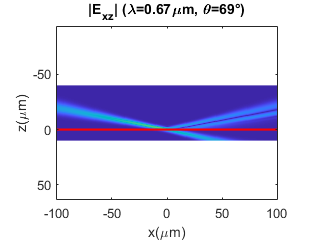

fig = figure;
ax = axes(fig);
figure(Position=[150,150,1500,300])
% Reduce data resolution for Live Script display
decimation_factor = 4;
zt_reduced = zt(1:decimation_factor:end);
Ut_reduced = Ut(1:decimation_factor:end, 1:decimation_factor:end);

% Create core visualization
h_img = imagesc(ax, -1e6*sp, 1e6*zt_reduced, abs(Ut_reduced));
hold(ax, 'on');

% Add interface lines
h_line1 = plot(ax, 1e6*[min(sp),max(sp)], [0,0], 'r', 'LineWidth', 1.5);
h_line2 = plot(ax, 1e6*[min(sp),max(sp)], 1e6*d_tf*[1,1], 'r', 'LineWidth', 1.5);
hold(ax, 'off');

% Configure axes
ax.XLabel.String = 'x(\mum)';
ax.YLabel.String = 'z(\mum)';
ax.Title.String = ['|E_{xz}| (\lambda=', num2str(lambda0_um,2), ...
                  '\mum, \theta=', num2str(rad2deg(theta),2), '°)'];
axis(ax, 'equal');
xlim(ax, 100*[-1, 1]);


% Force immediate rendering
drawnow limitrate;

% Cleanup handles (prevents serialization issues)
clear fig ax h_img h_line1 h_line2

## Helper Functions

### Angular spectrum propagation functions

function [A, fx] = angular_spectrum(U, x)
    Fs = 1/mean(diff(x));
    L = 2^nextpow2(length(x));
    A = fft(U, L, 2)/L;
    fx = (Fs/L)*[0,(1:(L/2-1)),-(1:L/2)];
end

function [U, x] = i_angular_spectrum(A, fx)
    dx = 1/mean(diff(fx));
    L = 2^nextpow2(length(fx));
    U = ifft(A*length(fx), L, 2);
    x = (dx/L)*(-L/2:L/2-1);
end

% Gaussian beam generation
function U = gb_complex_amplitude(P, x, z, k, w0, z0)
    w = w0*sqrt(1 + (z/z0).^2);
    if z ~= 0
        R = z.*(1 + (z0./z).^2);
        eta = atan(z/z0);
        phi = k*z + k*x.^2./(2*R) - eta;
    else
        phi = 0;
    end
    U = sqrt(2*P/pi)./w.*exp(-x.^2./w.^2).*exp(-1j*phi);
end

% TMM implementation
function E = tmm_3p_TM(E_TM, fx, z, n, d, lambda0)
lambda = lambda0./n;
arg = 1./lambda(1).^2 - fx.^2;

fz1 = sqrt(arg);
fz1(arg < 0) = 1j*fz1(arg < 0);
fz = (n./n(1)).*fz1;

theta = real(asin(fx*lambda(1)));
xi = sqrt(n.^2 - n(1)^2*sin(theta).^2);
q = xi./n.^2;
beta = 2*pi*d/lambda0*xi;

m11= cos(beta(2));
m12 = -1j/q(2)*sin(beta(2));
m21 = -1j*q(2)*sin(beta(2));
m22 = cos(beta(2));

rp = ((m11 + m12.*q(end,:)).*q(1,:) - (m21 + m22.*q(end,:)))./...
     ((m11 + m12.*q(end,:)).*q(1,:) + (m21 + m22.*q(end,:)));

tp = 2*q(1)./((m11 + m12.*q(end)).*q(1) + (m21 + m22.*q(end)));

z1 = z(z <= 0);
z2 = z((z > 0) & (z <= d));
z3 = z(z > d) - d;


p1 = 2*pi*z1*fz(1,:);
p2 = 2*pi*z2*fz(2,:);
p3 = 2*pi*z3*fz(3,:);

Ht = n(1)*E_TM;

E1 = -q(1)*Ht.*(exp(1j*p1) - rp.*exp(-1j*p1));
E2 = -q(2)*Ht.*(exp(1j*p2) - rp.*exp(-1j*p2));
E3 = -q(end)*tp.*Ht.*exp(1j*p3);

E = [E1;E2;E3];

end